# Fit stability analysis

## Correspondence between input noise and measured RMSE

sigma_vals = logspace(-1,4,150);
rmse_vals = arrayfun(@sigma2rmse, sigma_vals);

[r_sorted, ord] = unique(rmse_vals);
sigma_lookup = @(r) interp1(r_sorted, sigma_vals(ord), r, 'linear', "extrap");

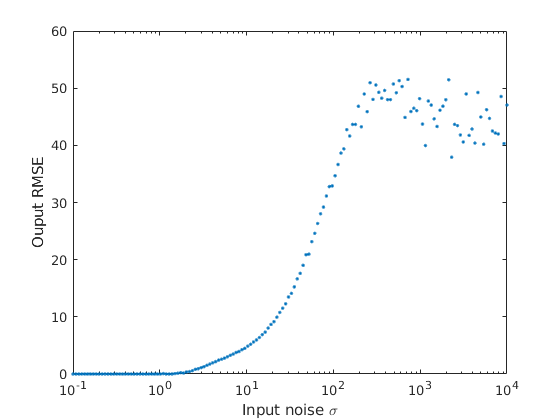


figure;
semilogx(sigma_vals, rmse_vals, '.');
xlabel 'Input noise \sigma'
ylabel 'Ouput RMSE'

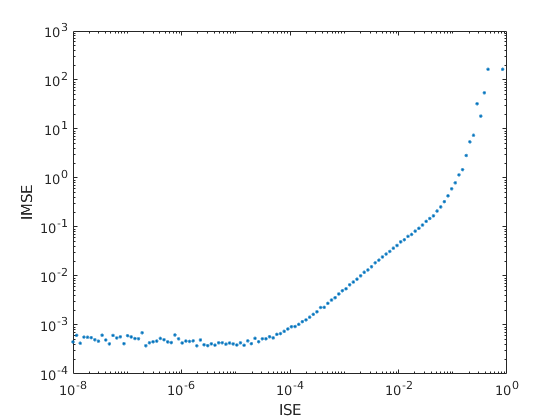

figure;
loglog(1./sigma_vals.^2, 1./rmse_vals.^2, '.');
xlabel 'ISE'
ylabel 'IMSE'

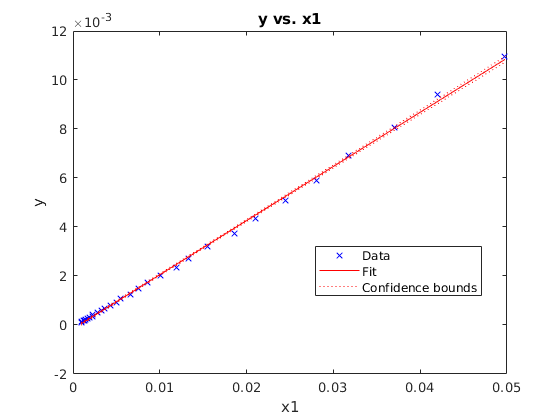

[ise_vals, ord] = sort(1./sigma_vals.^2);
imse_vals = 1./rmse_vals.^2;
imse_vals = imse_vals(ord);

linear_begin = find(ise_vals > 1e-4, 1);
linear_end = find(ise_vals > 1e-2, 1);
linear_range = linear_begin:linear_end;

ise_vals = ise_vals(linear_range);
imse_vals = imse_vals(linear_range);

mdl = fitlm(imse_vals, ise_vals);
figure;
plot(mdl);

sigma_lookup(7)

ans = 15.5746

Observe the linear regime:

sigma_vals = linspace(5,25,50);
rmse_vals = arrayfun(@sigma2rmse, sigma_vals);

mdl = fitlm(sigma_vals, rmse_vals)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    0.50624      0.030948    16.358    2.9153e-21
    x1             0.41988     0.0019204    218.64    1.2358e-73


Number of observations: 50, Error degrees of freedom: 48
Root Mean Squared Error: 0.08
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 4.78e+04, p-value = 1.24e-73

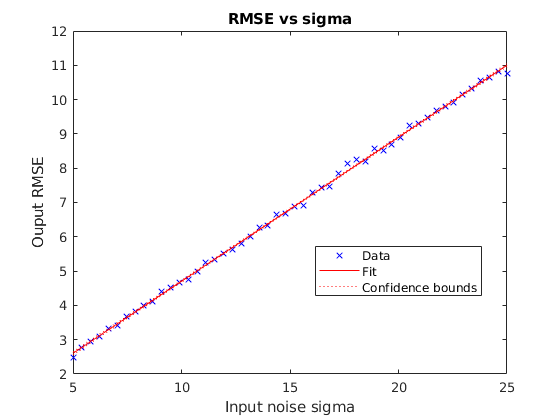


figure;
plot(mdl);
xlabel 'Input noise sigma'
ylabel 'Ouput RMSE'
title 'RMSE vs sigma'

Try the inverse, given RMSE = 7 cm, what is the corresponding $\sigma \;$?

rmse = 7;
sigma = rmse2sigma(rmse)

sigma = 15.3709

Verify that we recover the original RMSE, approximately because of the limited sample size:

rmse_original = sigma2rmse(sigma)

rmse_original = 6.9263

## Test 1: 1/2 Saturation at 100 neurons, measured with different ensemble sizes

We will test the stability of estimating the effective number of neurons to 1/2 saturation (*N*) using different numbers of ensemble sizes:

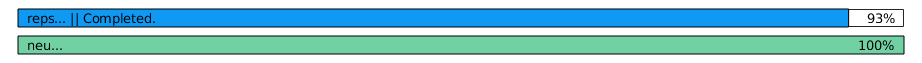

I_0 = 2.8660e+03

I_0 = estimate_I0

Given that *N *= 100, and the following correspondence:


$$\textrm{RMSE}=\sqrt{\;\frac{1}{I_{0\;} N}}$$


Find the appropriate value of $\sigma \;$ using the conversion functions shown earlier:

N = 100;
sigma = sqrt(1/(I_0*N))

sigma = 0.0019

Now check if 500 neurons are enough to retrieve the *N* value:

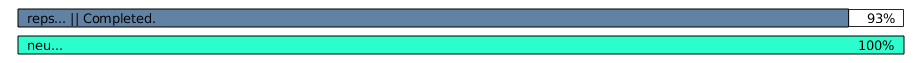

[n_neu, mse, ~, fr, gof] = general_decoding_curve('noise_sigma', sigma);

display(fr);

fr =      General model:
     fr(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0009657  (0.0008326, 0.001099)
       N =       98.77  (78.86, 118.7)

display(gof);

gof = struct with fields:
           sse: 1.4336e-04
       rsquare: 0.9903
           dfe: 17
    adjrsquare: 0.9897
          rmse: 0.0029


rmse = sqrt(mse);
err_sigmas = sigma_lookup(rmse);
err_sigmas2 = err_sigmas.^2;

[fr, gof] = createFit_infoSaturation(n_neu, mean(1./err_sigmas2))

fr =      General model:
     fr(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001929  (0.0001687, 0.0002171)
       N =       128.8  (103.8, 153.7)

gof = struct with fields:
           sse: 7.0563e-06
       rsquare: 0.9920
           dfe: 17
    adjrsquare: 0.9915
          rmse: 6.4427e-04


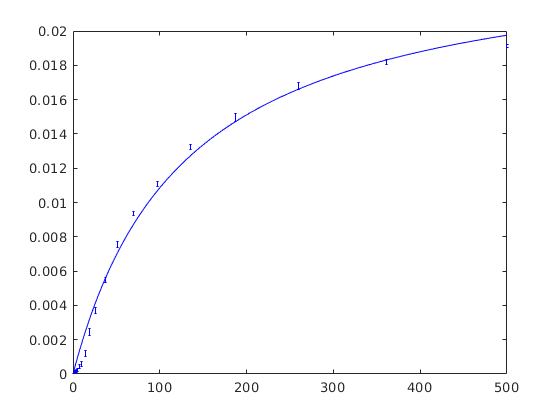


figure;
ep(n_neu, 1./err_sigmas2, 'b');
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)), 'b');

any(rmse(:) <= 0)

ans = logical
   0


As well as 50,000 neurons:

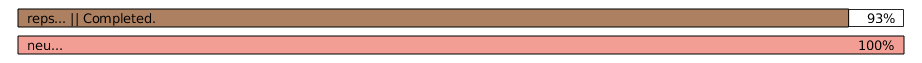

[n_neu, mse, ~, fr_large, gof_large] = general_decoding_curve('noise_sigma', sigma, 'n_cells', 50e3);

display(fr_large);

fr_large =      General model:
     fr_large(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0008875  (0.0007873, 0.0009877)
       N =       115.4  (101.2, 129.6)

display(gof_large);

gof_large = struct with fields:
           sse: 1.3621e-04
       rsquare: 0.9960
           dfe: 18
    adjrsquare: 0.9958
          rmse: 0.0028


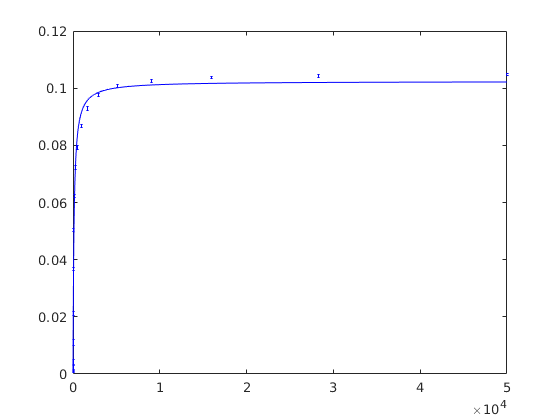

figure;
ep(n_neu, 1./mse, 'b');
hold on;
plot(1:max(n_neu), fr_large(1:max(n_neu)), 'b');

rmse = sqrt(mse);
err_sigmas = sigma_lookup(rmse);
err_sigmas2 = err_sigmas.^2;

[fr_large_sigma, gof_large_sigma] = createFit_infoSaturation(n_neu, mean(1./err_sigmas2))

fr_large_sigma =      General model:
     fr_large_sigma(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001801  (0.0001634, 0.0001969)
       N =       146.4  (131.6, 161.3)

gof_large_sigma = struct with fields:
           sse: 6.0732e-06
       rsquare: 0.9974
           dfe: 18
    adjrsquare: 0.9972
          rmse: 5.8086e-04


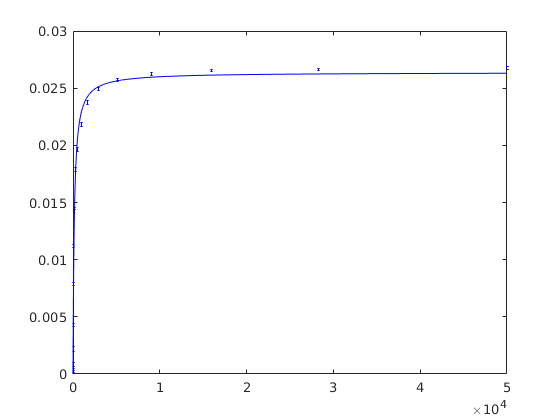


figure;
ep(n_neu, 1./err_sigmas2, 'b');
hold on;
plot(1:max(n_neu), fr_large_sigma(1:max(n_neu)), 'b');

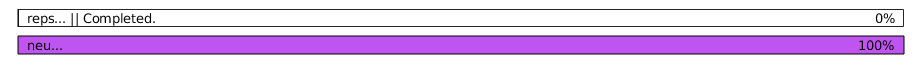

my_ncells = 2000;
my_sigma = 10;
[n_neu, mse, mse_sh] = general_decoding_curve('n_cells', my_ncells, 'noise_sigma', my_sigma, 'n_reps', 1, 'approx_samp', 10);

sigma_err = sigma_lookup(sqrt(mse));
is2e = 1./sigma_err.^2;

[fr, gof] = createFit_infoSaturation(n_neu, mean(is2e,1))

fr =      General model:
     fr(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001433  (0.0001145, 0.0001721)
       N =       60.44  (46.16, 74.72)

gof = struct with fields:
           sse: 8.7887e-07
       rsquare: 0.9882
           dfe: 8
    adjrsquare: 0.9867
          rmse: 3.3145e-04


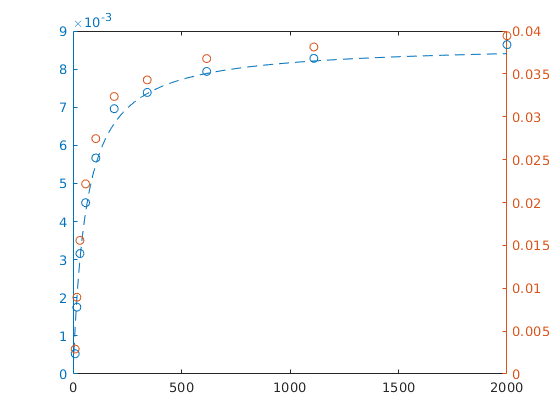


figure;
yyaxis left
plot(n_neu, mean(is2e,1), 'o');
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)));
yyaxis right
plot(n_neu, mean(1./mse,1), 'o');

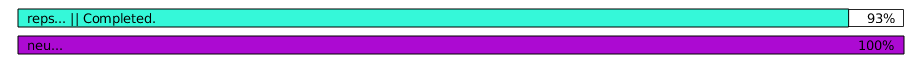

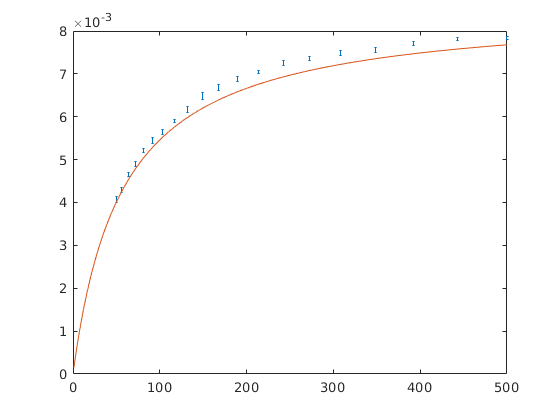

I_0 = 1.5121e-04

ci = 	1.0e+-3 *

    0.1344
    0.1681


lm =      General model:
     lm(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001512  (0.0001344, 0.0001681)
       N =       56.52  (48.36, 64.67)

t_ = tic;
[I_0, ci, lm] = estimate_I0

toc(t_)

Elapsed time is 151.071403 seconds.


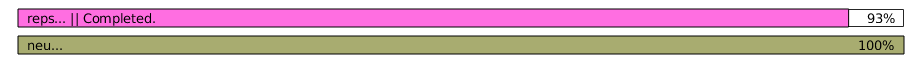

t_ = tic;
[n_neu, mse, mse_sh, fr, gof] = general_decoding_curve('n_min', 50, 'n_cells', 2000);

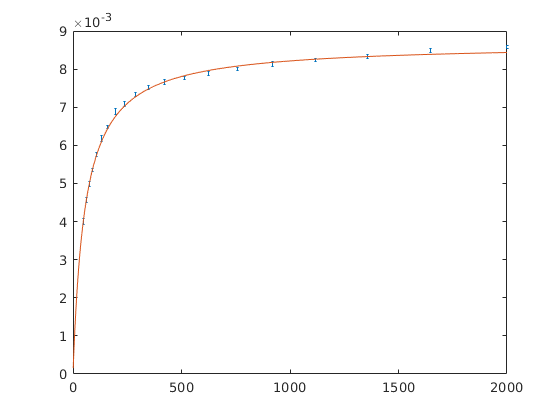

figure;
ep(n_neu, 1./mse);
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)));

toc(t_)

Elapsed time is 472.438111 seconds.


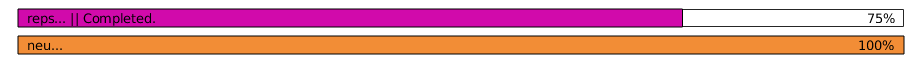

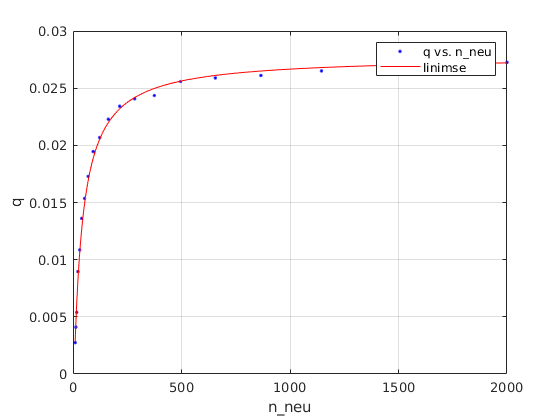

%predefined_N = 100;
derived_sigma = 12.34;%sqrt(1./(fr.I_0 * predefined_N));
t_ = tic;
[n_neu, mse, mse_sh, fr, gof] = general_decoding_curve('n_min', 10, 'n_cells', 2000, 'noise_sigma', derived_sigma, 'n_reps', 4);

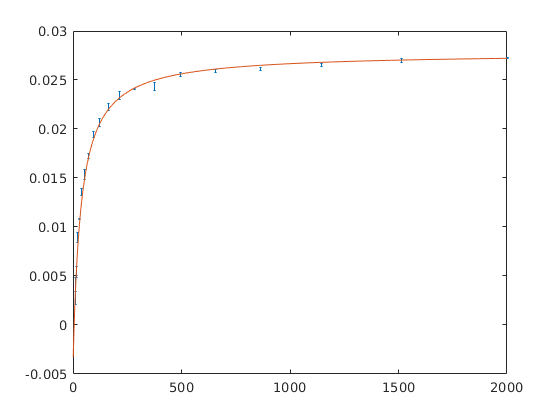

figure;
ep(n_neu, 1./mse);
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)));

toc(t_)

Elapsed time is 90.217077 seconds.



fr

fr =      General model:
     fr(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0008846  (0.0007286, 0.001041)
       N =       36.07  (31.08, 41.06)
       c =   -0.004131  (-0.005707, -0.002555)

t_ = tic;
[n_neu0, mse0, mse_sh0, fr0, gof0] = general_decoding_curve('n_min', 50, 'n_cells', 300, 'noise_sigma', 0, 'n_reps', 16, 'approx_samp', 100, 'linear_only', true);

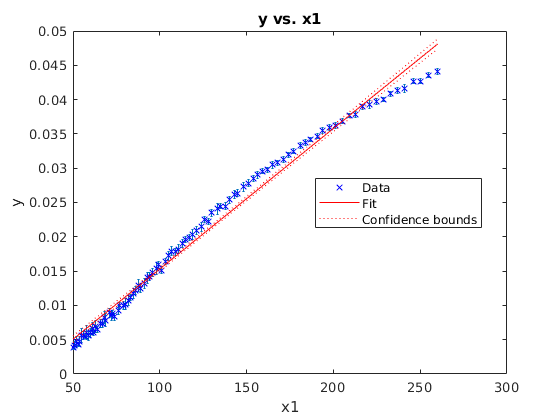

figure;
ep(n_neu0, 1./mse0);

lin_mdl = fitlm(n_neu0, mean(1./mse0));
hold on;
plot(lin_mdl);

%hold on;
%plot(1:max(n_neu0), fr0(1:max(n_neu0)));
toc(t_)

Elapsed time is 110.949599 seconds.



fr0

fr0 =      General model:
     fr0(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0003747  (0.0003494, 0.0004001)
       N =       392.8  (339.8, 445.7)
       c =    -0.01371  (-0.01484, -0.01257)

lin_mdl

lin_mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)    -0.0051738     0.0003499    -14.787    8.1645e-26
    x1             0.00020489    2.4826e-06     82.532    1.3031e-86


Number of observations: 92, Error degrees of freedom: 90
Root Mean Squared Error: 0.00143
R-squared: 0.987,  Adjusted R-Squared: 0.987
F-statistic vs. constant model: 6.81e+03, p-value = 1.3e-86

ci = lin_mdl.coefCI;
ci(2,:)

ans = 	1.0e+-3 *

    0.2000    0.2098


I0_value = fr.I_0;%lin_mdl.Coefficients.Estimate(2)
predetermined_N = 100;
conversion_factor = mdl.Coefficients.Estimate(2);
derived_sigma = 1./sqrt(I0_value*predetermined_N*conversion_factor) %should be ~8

derived_sigma = 17.5197

t_ = tic;
[n_neu, mse, mse_sh, fr, gof] = general_decoding_curve('approx_samp', 25, 'n_min', 10, 'n_cells', 2000, 'noise_sigma', derived_sigma, 'n_reps', 16, 'linear_only', true);

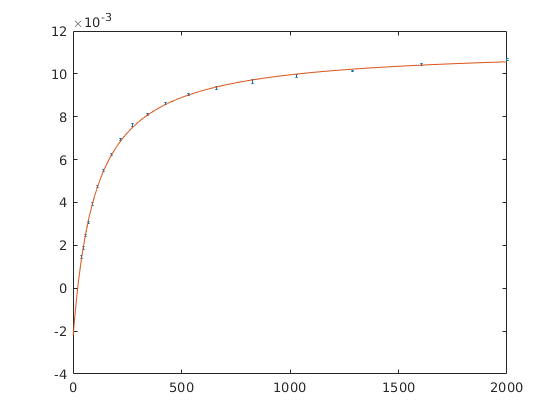

figure;
ep(n_neu, 1./mse);
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)));

toc(t_)

Elapsed time is 96.242967 seconds.



fr

fr =      General model:
     fr(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001304  (0.0001167, 0.0001442)
       N =         104  (95.4, 112.7)
       c =   -0.002337  (-0.002748, -0.001926)

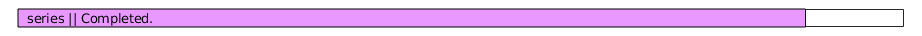

s_values = 0:2.5:20;
progressbar('series')
for i = 1:numel(s_values)
    [n_series{i}, mse_series{i}, ~, fr_series{i}, gof_series{i}] = general_decoding_curve('approx_samp', 25, 'n_min', 10, 'n_cells', 500, 'noise_sigma', s_values(i), 'n_reps', 16, 'linear_only', true);
    progressbar(i/numel(s_values));
end

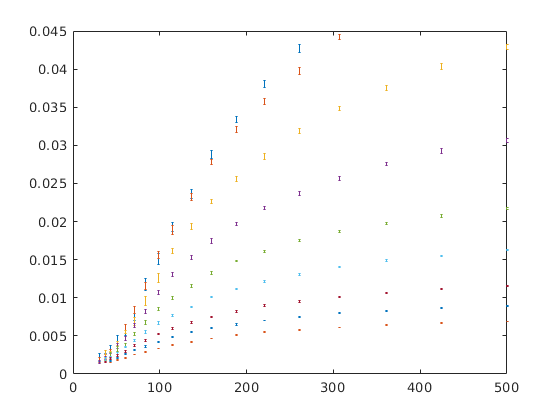

figure;
for i = 1:numel(s_values)
    ep(n_series{i}, 1./mse_series{i}); hold on;
end

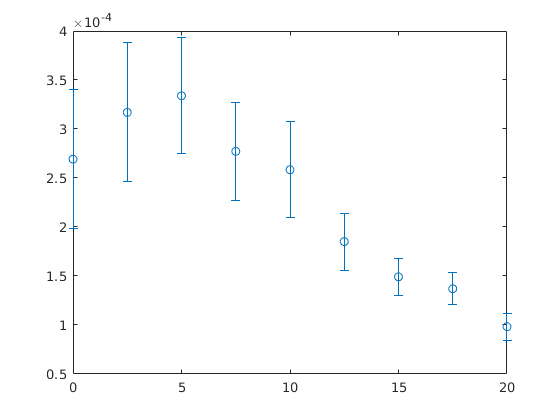


figure;
errorbar(s_values, cellfun(@(x)x.I_0, fr_series), cellfun(@(x)get_ci(x,1), fr_series), 'o');

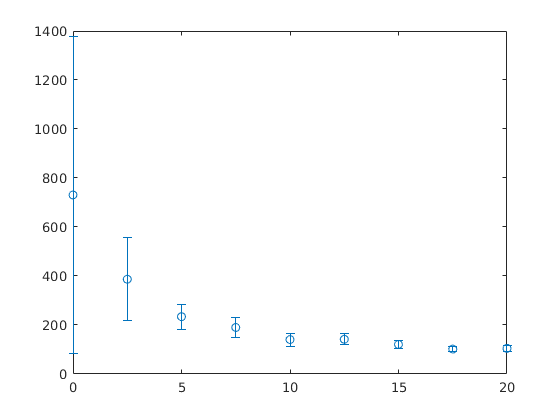

figure;
errorbar(s_values, cellfun(@(x)x.N, fr_series), cellfun(@(x)get_ci(x,2), fr_series), 'o');

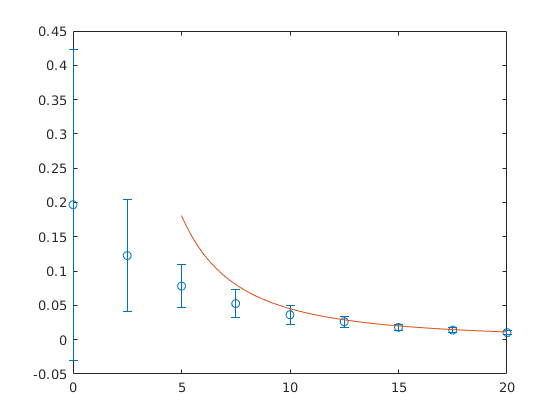

figure;
I0N_series = cellfun(@(x)x.N*x.I_0, fr_series);
I0N_conf = cellfun(@(x)x.I_0*get_ci(x,2) + x.N*get_ci(x,1), fr_series);
errorbar(s_values, I0N_series, I0N_conf, 'o');
hold on;
x_ = 5:0.01:20;
plot(x_, 1./x_.^2 / conversion_factor);

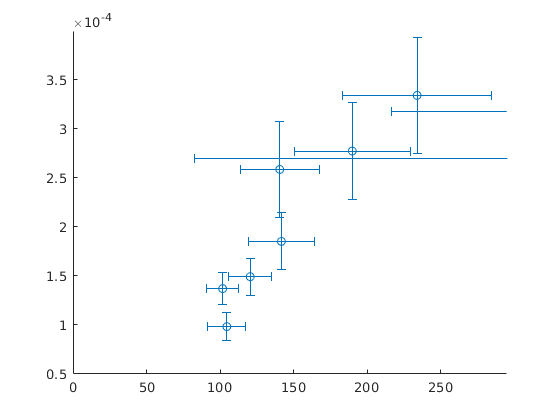

figure;
N_series = cellfun(@(x)x.N, fr_series);
N_conf = cellfun(@(x)get_ci(x,2), fr_series);

I0_series = cellfun(@(x)x.I_0, fr_series);
I0_conf = cellfun(@(x)get_ci(x,1), fr_series);

%scatter(cellfun(@(x)x.N, fr_series), cellfun(@(x)x.I_0, fr_series));
hold on;
errorbar(N_series, I0_series, I0_conf, I0_conf, N_conf, N_conf, 'o');

function rmse = sigma2rmse(sigma)
[~, mse] = general_decoding_curve('noise_sigma', sigma,...
    'approx_samp', 1,...
    'n_reps', 1,...
    'n_cells', 1,...
    'response_type', "gaussian",...
    'model_type', "rate coding",...
    'progress', false); 
rmse = sqrt(mean(mse));
end

function sigma = rmse2sigma(rmse)
sigma = fzero(@(x) sigma2rmse(x) - rmse, 1);
end

function [I_0, ci, fr] = estimate_I0
[n_neu, mse, mse_sh, fr, gof] = general_decoding_curve('n_min', 50);
figure;
ep(n_neu, 1./mse);
hold on;
plot(1:max(n_neu), fr(1:max(n_neu)));
I_0 = fr.I_0;
ci = confint(fr);
ci = ci(:,1);
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end

function ci = get_ci(fit_mdl, idx)
q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end